clc; clear all; close all;
img_path = fullfile('fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

1.

RGB1 = imread(string(fullfile(img_path, T{9,1})));
R1=RGB1(:,:,1);
G1=RGB1(:,:,2);
B1=RGB1(:,:,3);

margen1=300;
centroideY1=1056;
centroideX1=1538;

OD_zoomR1 = R1(centroideY1-margen1:centroideY1+margen1, centroideX1-margen1:centroideX1+margen1);
OD_zoomG1 = G1(centroideY1-margen1:centroideY1+margen1, centroideX1-margen1:centroideX1+margen1);
OD_zoomB1 = B1(centroideY1-margen1:centroideY1+margen1, centroideX1-margen1:centroideX1+margen1);
OD_zoomRGB1 = cat(3, OD_zoomR1, OD_zoomG1, OD_zoomB1);%Para juntar las 3 layers

2.

RGB2 = imread(string(fullfile(img_path, T{32,1})));
R2=RGB2(:,:,1);
G2=RGB2(:,:,2);
B2=RGB2(:,:,3);

margen2=300;
centroideY2=1345;
centroideX2=2175;

OD_zoomR2 = R2(centroideY2-margen2:centroideY2+margen2, centroideX2-margen2:centroideX2+margen2);
OD_zoomG2 = G2(centroideY2-margen2:centroideY2+margen2, centroideX2-margen2:centroideX2+margen2);
OD_zoomB2 = B2(centroideY2-margen2:centroideY2+margen2, centroideX2-margen2:centroideX2+margen2);
OD_zoomRGB2 = cat(3, OD_zoomR2, OD_zoomG2, OD_zoomB2);

3.

RGB3 = imread(string(fullfile(img_path, T{48,1})));
R3=RGB3(:,:,1);
G3=RGB3(:,:,2);
B3=RGB3(:,:,3);

margen3=300;
centroideY3=1110;
centroideX3=1612;

OD_zoomR3 = R3(centroideY3-margen3:centroideY3+margen3, centroideX3-margen3:centroideX3+margen3);
OD_zoomG3 = G3(centroideY3-margen3:centroideY3+margen3, centroideX3-margen3:centroideX3+margen3);
OD_zoomB3 = B3(centroideY3-margen3:centroideY3+margen3, centroideX3-margen3:centroideX3+margen3);
OD_zoomRGB3 = cat(3, OD_zoomR3, OD_zoomG3, OD_zoomB3);

4.

RGB4 = imread(string(fullfile(img_path, T{69,1})));
R4=RGB4(:,:,1);
G4=RGB4(:,:,2);
B4=RGB4(:,:,3);

margen4=300;
centroideY4=1007;
centroideX4=2420;

OD_zoomR4 = R4(centroideY4-margen4:centroideY4+margen4, centroideX4-margen4:centroideX4+margen4);
OD_zoomG4 = G4(centroideY4-margen4:centroideY4+margen4, centroideX4-margen4:centroideX4+margen4);
OD_zoomB4 = B4(centroideY4-margen4:centroideY4+margen4, centroideX4-margen4:centroideX4+margen4);
OD_zoomRGB4 = cat(3, OD_zoomR4, OD_zoomG4, OD_zoomB4);

5.

RGB5 = imread(string(fullfile(img_path, T{86,1})));
R5=RGB5(:,:,1);
G5=RGB5(:,:,2);
B5=RGB5(:,:,3);

margen5=300;
centroideY5=1156;
centroideX5=2374;

OD_zoomR5 = R5(centroideY5-margen5:centroideY5+margen5, centroideX5-margen5:centroideX5+margen5);
OD_zoomG5 = G5(centroideY5-margen5:centroideY5+margen5, centroideX5-margen5:centroideX5+margen5);
OD_zoomB5 = B5(centroideY5-margen5:centroideY5+margen5, centroideX5-margen5:centroideX5+margen5);
OD_zoomRGB5 = cat(3, OD_zoomR5, OD_zoomG5, OD_zoomB5);

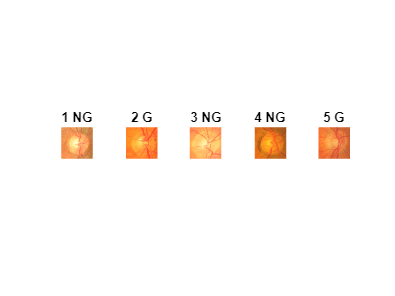

figure;
subplot(1, 5, 1);
imshow(OD_zoomRGB1);
title('1 NG');
subplot(1, 5, 2);
imshow(OD_zoomRGB2);
title('2 G');
subplot(1, 5, 3);
imshow(OD_zoomRGB3);
title('3 NG');
subplot(1, 5, 4);
imshow(OD_zoomRGB4);
title('4 NG');
subplot(1, 5, 5);
imshow(OD_zoomRGB5);
title('5 G');

Median filtering

OD_zoomR1m=medfilt2(OD_zoomR1,[3 3],"symmetric");
OD_zoomG1m=medfilt2(OD_zoomG1,[3 3],"symmetric");
OD_zoomB1m=medfilt2(OD_zoomB1,[3 3],"symmetric");

OD_zoomR2m=medfilt2(OD_zoomR2,[3 3],"symmetric");
OD_zoomG2m=medfilt2(OD_zoomG2,[3 3],"symmetric");
OD_zoomB2m=medfilt2(OD_zoomB2,[3 3],"symmetric");

OD_zoomR3m=medfilt2(OD_zoomR3,[3 3],"symmetric");
OD_zoomG3m=medfilt2(OD_zoomG3,[3 3],"symmetric");
OD_zoomB3m=medfilt2(OD_zoomB3,[3 3],"symmetric");

OD_zoomR4m=medfilt2(OD_zoomR4,[3 3],"symmetric");
OD_zoomG4m=medfilt2(OD_zoomG4,[3 3],"symmetric");
OD_zoomB4m=medfilt2(OD_zoomB4,[3 3],"symmetric");

OD_zoomR5m=medfilt2(OD_zoomR5,[3 3],"symmetric");
OD_zoomG5m=medfilt2(OD_zoomG5,[3 3],"symmetric");
OD_zoomB5m=medfilt2(OD_zoomB5,[3 3],"symmetric");

Calculo el histograma de cada canal de cada imagen

[histR1, binR1] = imhist(OD_zoomR1m);
[histG1, binG1] = imhist(OD_zoomG1m);
[histB1, binB1] = imhist(OD_zoomB1m);

[histR2, binR2] = imhist(OD_zoomR2m);
[histG2, binG2] = imhist(OD_zoomG2m);
[histB2, binB2] = imhist(OD_zoomB2m);

[histR3, binR3] = imhist(OD_zoomR3m);
[histG3, binG3] = imhist(OD_zoomG3m);
[histB3, binB3] = imhist(OD_zoomB3m);

[histR4, binR4] = imhist(OD_zoomR4m);
[histG4, binG4] = imhist(OD_zoomG4m);
[histB4, binB4] = imhist(OD_zoomB4m);

[histR5, binR5] = imhist(OD_zoomR5m);
[histG5, binG5] = imhist(OD_zoomG5m);
[histB5, binB5] = imhist(OD_zoomB5m);

Hago la media de todos los histogramas, los que  voy a utilizar como plantilla

meanHistR = (histR1 + histR2 + histR3 + histR5 + histR5) / 5;
meanHistG = (histG1 + histG2 + histG3 + histG5 + histG5) / 5;
meanHistB = (histB1 + histB2 + histB3 + histB5 + histB5) / 5;

%Aquí puedo añadir un código que exporte el histograma que se va a usar
%como plantilla y así no tengo que runear este código todo el rato.

RGB**a** (de **a**nálisis)

calculo la correlación de cada window con esta fórmula y encuentro cual es el window con mayor correlación

RGBa = imread(string(fullfile(img_path, T{252,1})));%Voy a buscar el OD de esta imagen
margen=300;%este es el tamaño de las ventanas que se van a usar, tiene que coincidir con el tamaño de las plantillas
meanHistRGB=[meanHistR meanHistG meanHistB];

tR=0.5;
tG=2;
tB=1;

[alto, ancho, ~] = size(RGBa);
CM=zeros(alto-margen*2,ancho-margen*2);
diff=zeros(alto-margen*2,ancho-margen*2);
dif=zeros(alto-margen*2,ancho-margen*2,3);
for i=1:3
    for x=margen+1:ancho-margen
        for y=margen+1:alto-margen
            layer_zoom=RGBa(y-margen:y+margen, x-margen:x+margen, i);
            [hist_layer, ~] = imhist(layer_zoom);
            diff(y-margen,x-margen)=sum(bsxfun(@minus, hist_layer, meanHistRGB(i)).^2);
        end
        
    end
    dif(:,:,i)=diff;
end

c=1/(1+dif);
CM = c(:,:,1).*tR + c(:,:,2).*tG + c(:,:,3);
